# **Model for parametric acoustic sources**

**2024-03-06**

**Vibration and Acoustic Transducers Laboratory**

**Pohang University of Science and Technology**

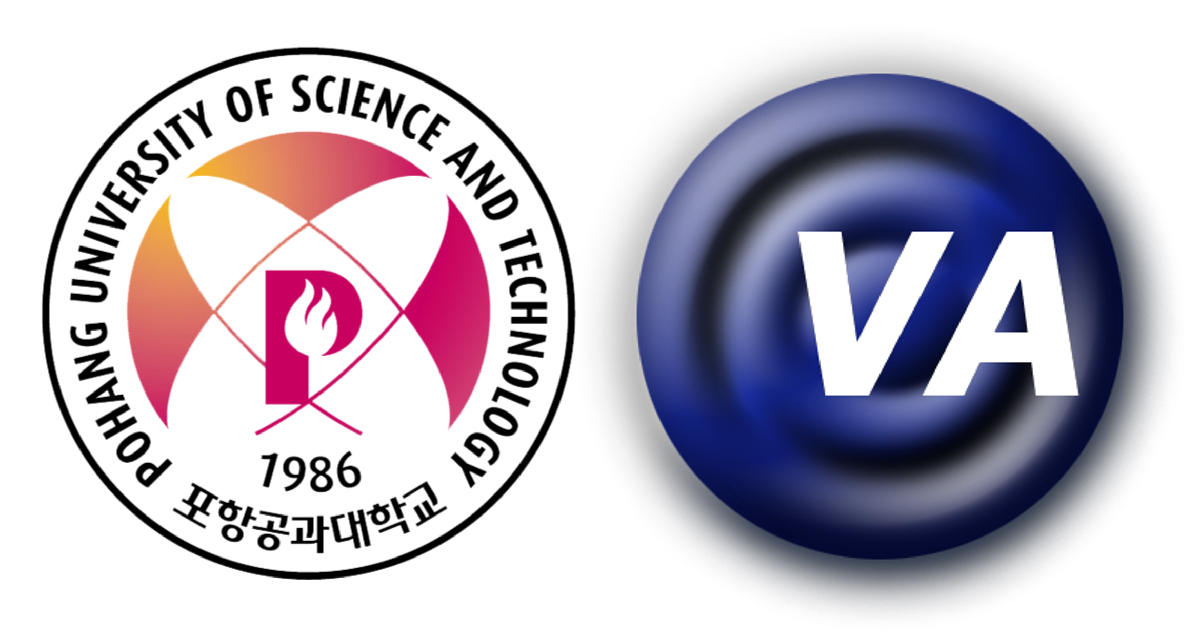

***Woongji Kim***

[wj.kim@postech.ac.kr](mailto:wj.kim@postech.ac.kr)

clear

beta = 3.5;
rho = 998;
c   = 1481;

P0 = logspace(3,6,31)';
R0 = 1;
f0 = 1e6;
f = 1e5;

alphaR0dB = [1e-5 1e-3 1e-2 0.1 0.2 0.5 1 2 5 10];
alpha_ = alphaR0dB/(20*log10(exp(1)));

newcolors = parula(length(alphaR0dB)+2);
newcolors = newcolors(2:end-1,:);
colororder(newcolors);

r_ = logspace(-3,3,61);

For the first in the integrand, we desire a smooth function having the limits

 
$$\matrix{
1 & (r' \ll R_0 f_0 / f) \cr
-jf_0 R_0/f r' & (r' \gg R_0 f_0 / f)
}$$


and we choose


$$S=\left(1+j \frac{f r'}{f_0 R_0} \right)^{-1}$$


Sprd = @(f,r,f0,R0) (1+1j.*f.*r./(f0.*R0)).^-1;


$$\chi = \frac{2 \pi \beta P_0 R_0 f_0}{\rho c^3} = \frac{X}{Y}$$


chi = @(f0,R0,P0) 2*pi*beta.*P0.*R0.*f0/(rho*c^3);
chi_ = chi(f0,R0,P0);
L0 = 20*log10(chi(f0,R0,P0))+281;


$$\sigma = 2 \chi \sinh^{-1}{\left( \frac{r'}{R_0} \right)}$$


sigma = @(r,R0,chi) 2*chi.*asinh(r./R0);


$$K \equiv 3 \left( \frac{\sigma}{2\pi} \right)^2$$


K = @(sigma) 3*(sigma./(2*pi)).^2;


$$T^2(r') = \frac{2}{K^2} \left( \frac{1+K}{(1+2K)^{1/2}} - 1 \right) e^{- 2 \alpha r'$$


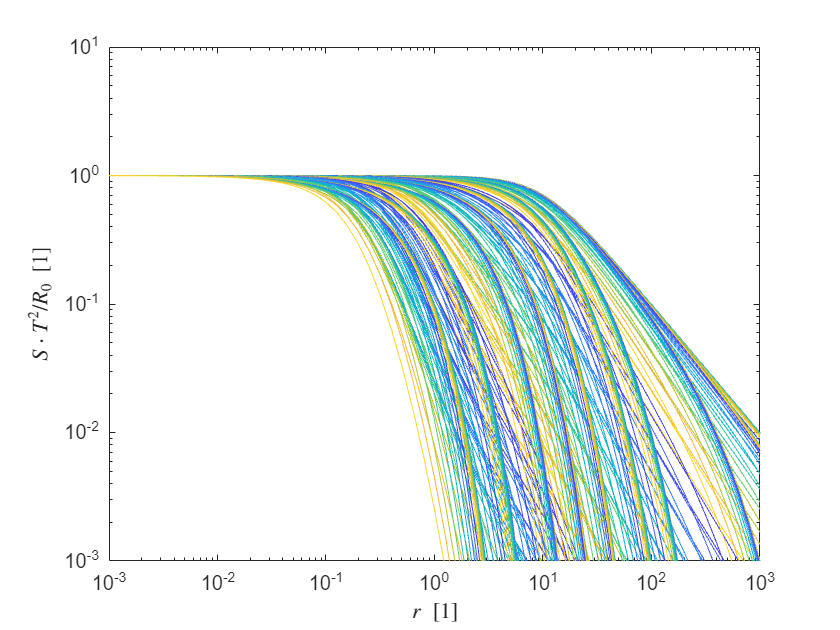

% Tsq = @(K, r, alpha) (2./K.^2.*((1+K)./sqrt(1+2.*K)-1)).*exp(-2*alpha.*r);
% Tsq0 = @(r, alpha) exp(-2*alpha.*r);

Tsq = @(K, r, alpha) (2./K.^2.*((1+K)./sqrt(1+2.*K)-1)).*exp(-2*alpha.*r).*(K>1e-5) + exp(-2*alpha.*r).*(K<=1e-5);
% TsqSimplified = @(sigma, r, alpha) (1+(sigma/4).^2).^(-1).*exp(-2*alpha.*r);

% Tsq_ = Tsq(K(sigma(r_,R0,chi(f0,R0,P0))), r_, alpha);
% loglog(r_,Tsq_)

for iP0 = 1:length(P0)
    P = P0(iP0);
    for ialpha = 1:length(alphaR0dB)
        alpha = alpha_(ialpha);
        Sprd_Tsq_(iP0,ialpha,:) = Sprd(f,r_,f0,R0).*Tsq(K(sigma(r_,R0,chi(f0,R0,P0(iP0)))),r_,alpha)/R0;
        % Sprd_Tsq_(iP0,ialpha,:) = Sprd(f,r_,f0,R0).*Tsq(K(sigma(r_,R0,chi(f0,R0,P0(iP0)))),r_,alpha)/R0.*(K(sigma(r_,R0,chi(f0,R0,P0(iP0))))>4e-7) + ...
        %     Sprd(f,r_,f0,R0).*Tsq0(r_,alpha)/R0.*(K(sigma(r_,R0,chi(f0,R0,P0(iP0))))<=4e-7);
    end
end

p4 = loglog(r_,reshape(abs(Sprd_Tsq_),length(P0)*length(alphaR0dB),[]));
xlabel('$r \ [1]$','Interpreter','latex')
ylabel('$S \cdot T^2/R_0 \ [1]$','Interpreter','latex')
ylim([1e-3 1e1])

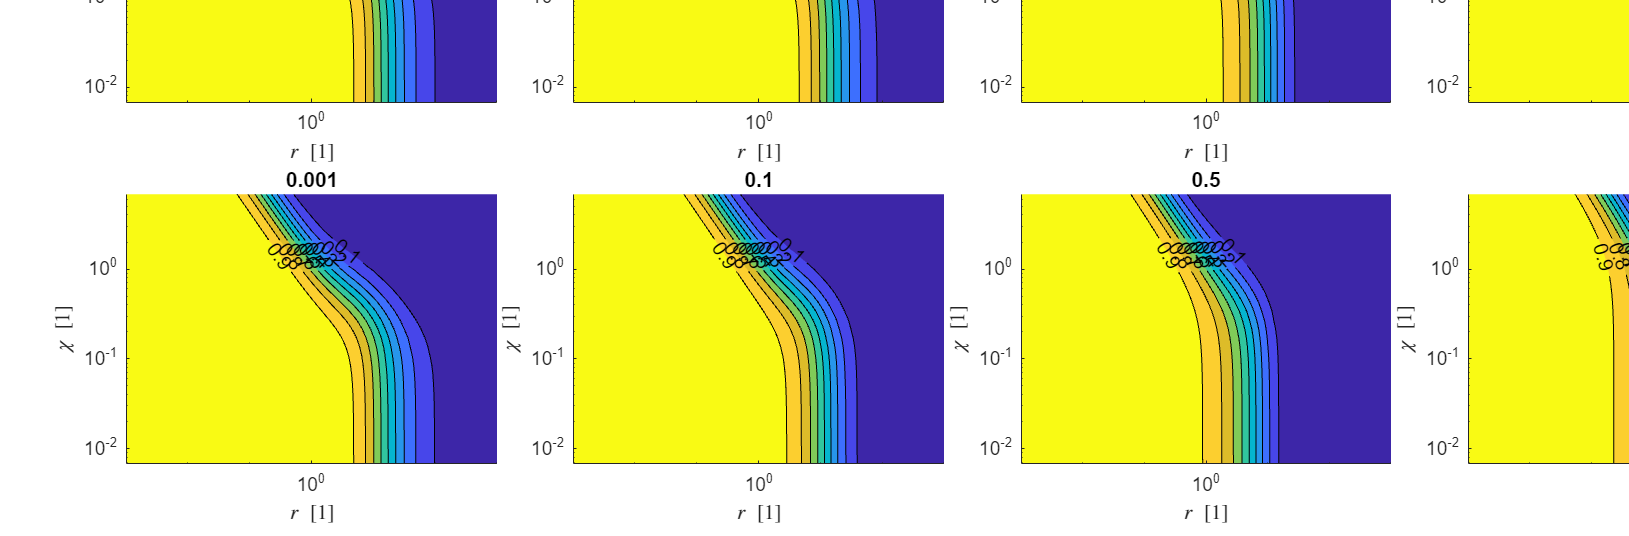

figure = figure('Units','inches','Position',[0 0 3.25*ceil(10/2)+0.5 2.5*2+0.5]);
tile = tiledlayout(2,ceil(10/2),'TileIndexing','columnmajor','TileSpacing','tight', ...
    'Unit','inches','Position',[0.625+0.25 0.5 3.25*ceil(10/2)-1.25 2.5*2-0.625]);

for ialpha = 1:length(alphaR0dB)
    axes = nexttile(tile);
    hold(axes,'on');
    contourf(r_,chi_,squeeze(abs(Sprd_Tsq_(:,ialpha,:))),0:0.1:1,'ShowText','on');
    xlabel('$r \ [1]$','Interpreter','latex')
    ylabel('$\chi \ [1]$','Interpreter','latex')
    title(axes, num2str(alphaR0dB(ialpha)))
    set(gca,'BoxStyle','full','Layer','top','XMinorTick','on','XScale','log',...
        'YMinorTick','on','YScale','log');
    hold(axes,'off');
end

% syms rr
for ialpha = 1:length(alphaR0dB)
    alpha = alpha_(ialpha);
    % g_vpa(ialpha,:) = vpaintegral(chi(f0,R0,P0).*(f/f0).^2.*Sprd(f,rr,f0,R0).*Tsq(K(sigma(rr,R0,chi(f0,R0,P0))), rr, alpha)/R0,1e-1,1e2);
    g(ialpha,:) = integral(@(rr) chi(f0,R0,P0).*(f/f0).^2.*Sprd(f,rr,f0,R0).*Tsq(K(sigma(rr,R0,chi(f0,R0,P0))), rr, alpha)/R0, 1e-1, 1e2, 'ArrayValued',true);
    % g_vpaSimplified(ialpha,:) = vpaintegral(chi(f0,R0,P0).*(f/f0).^2.*Sprd(f,rr,f0,R0).*TsqSimplified(sigma(rr,R0,chi(f0,R0,P0)), rr, alpha)/R0,1e-1,1e2);
end

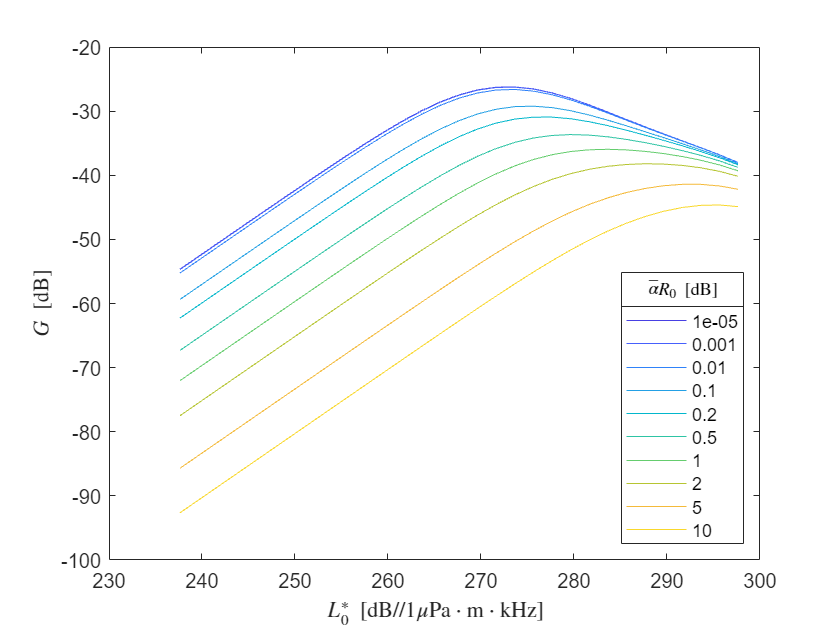



% p1 = plot(L0, 20*log10(abs(g_vpa')));
p1 = plot(L0, 20*log10(abs(g')));
% p11 = plot(L0, 20*log10(abs(g_vpaSimplified')));
for ialpha = 1:length(alphaR0dB)
    set(p1(ialpha),'DisplayName',num2str(alphaR0dB(ialpha)))
end
xlabel('$L_0^* \ [\mathrm{dB}// 1\mathrm{\mu Pa \cdot m \cdot kHz} ]$','Interpreter','latex')
ylabel('$G \ [\mathrm{dB}]$','Interpreter','latex')
lgd1 = legend('Location','southeast');
title(lgd1,'$\bar{\alpha} R_0 \ [\mathrm{dB}]$','Interpreter','latex');

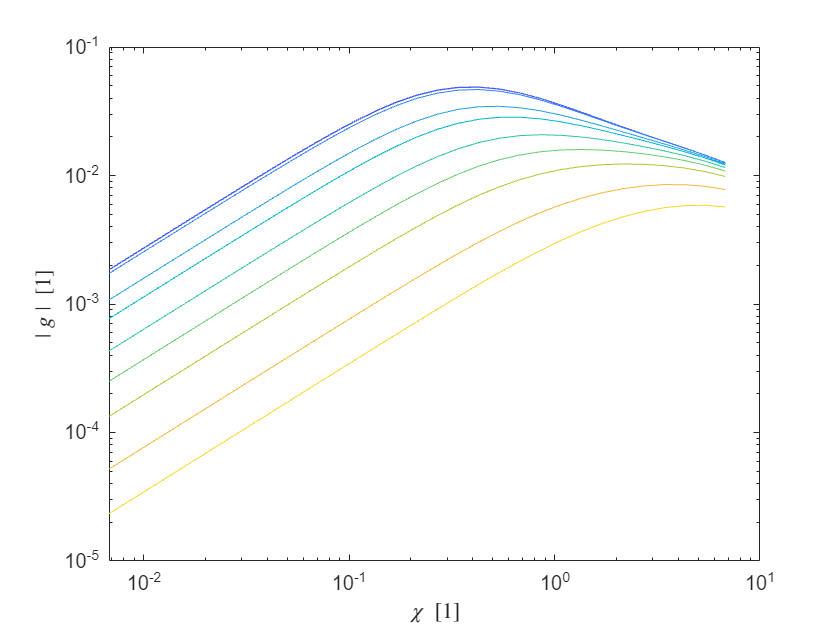



% p2 = loglog(chi_,abs(g_vpa'));
p2 = loglog(chi_,abs(g'));
xlabel('$\chi \ [1]$','Interpreter','latex')
ylabel('$\mid g \mid \ [1]$','Interpreter','latex')

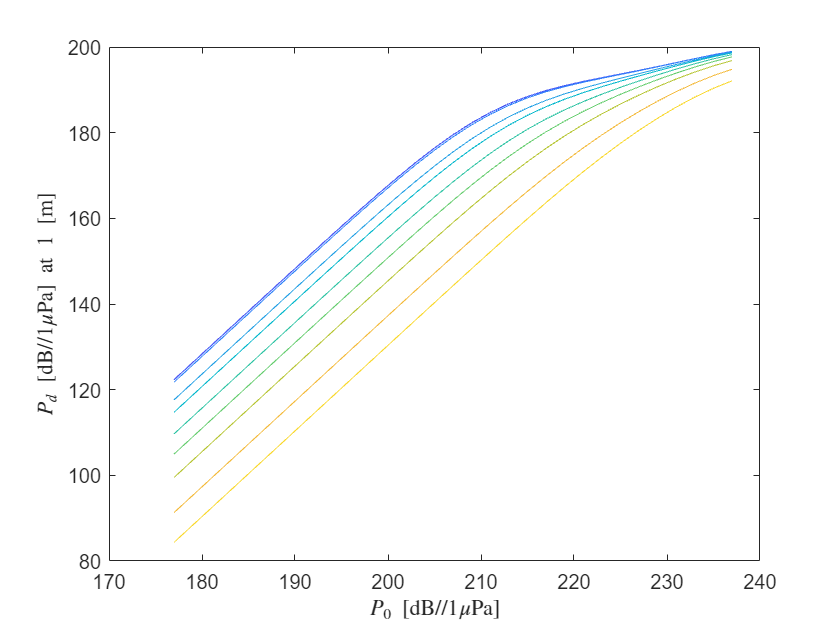

rObs = 1; % at observation distance, e.g. 1 [m]
% pObs = g_vpa*R0.*repmat(P0,1,length(alphaR0dB))'/rObs;
pObs = g*R0.*repmat(P0,1,length(alphaR0dB))'/rObs;

p3 = plot(20*log10(P0/1e-6/sqrt(2)),20*log10(abs(pObs)/1e-6/sqrt(2)));
xlabel('$P_0 \ [\mathrm{dB}// 1\mathrm{\mu Pa} ]$','Interpreter','latex')
ylabel('$P_d \ [\mathrm{dB}// 1\mathrm{\mu Pa} ] \ \mathrm{at} \ 1 \ [\mathrm{m}]$','Interpreter','latex')

% %% Set up the Import Options and import the data
% opts = delimitedTextImportOptions("NumVariables", 2);
% 
% % Specify range and delimiter
% opts.DataLines = [1, Inf];
% opts.Delimiter = "\t";
% 
% % Specify column names and types
% opts.VariableNames = ["fOBS", "pOBS"];
% opts.VariableTypes = ["double", "double"];
% 
% % Specify file level properties
% opts.ExtraColumnsRule = "ignore";
% opts.EmptyLineRule = "read";
% 
% % Import the data
% tbl = readtable("C:\Users\wj\MATLAB Drive\Workspace\SPPALs\experiments\PFW - OBS - SPPALs_Exp_Results_Total_modified_by_WJ (230505).xlsx.txt", opts);
% 
% %% Convert to output type
% fOBS = tbl.fOBS;
% pOBS = tbl.pOBS;
% 
% %% Clear temporary variables
% clear opts tbl

% beta = 1.2;
% rho = 1.21;
% c   = 343;
% Pr = 0.75;
% mu0 = 1.81e-5;
% muBmu0 = 0.6;
% gamma = 1.402;
% delta = mu0/rho*(4/3+muBmu0+(gamma-1)/Pr);
% 
% a = 50e-3; % Radiator size
% 
% fq = 60e3:100:90e3;
% pOBS_ = interp1(fOBS,pOBS,fq)+14; % curve M을 P0를 보정한 것임
% pOBS_ = 2e-5*10.^(pOBS_/20);
% semilogy(fq,pOBS_)
% 
% f_ = 500:100:17e3;
% % f_ = 1e3;
% f0 = 72.8e3;
% 
% alpha_ = @(f,f0) delta/c^3*((2*pi*f).^2+(2*pi*f0).^2)/2;
% % alpha_total = (alpha_c + alpha_s)/2, Taper function에 exp(-2*alpha*r)로 들어가니까 평균을 내었음
% 
% f0_ = f0 + f_/2;
% P0_ = sqrt(interp1(fq,pOBS_,f0).*interp1(fq,pOBS_,f0+f_));
% R0_ = pi*f0_/c*a^2;

% % g_vpa_OBS = vpaintegral(chi(f0_,R0_,P0_).*(f_/f0_).^2.*Sprd(f_,rr,f0_,R0_).*Tsq(K(sigma(rr,R0_,chi(f0_,R0_,P0_))), rr, alpha_(f_,f0))./R0_,1e-1,1e2);
% 
% % g_vpa_OBS = vpaintegral(chi(f0_,R0_,P0_).*(f_/f0_).^2.*Sprd(f_,rr,f0_,R0_).*TsqSimplified(sigma(rr,R0_,chi(f0_,R0_,P0_)), rr, alpha_(f_,f0))./R0_,1e-1,1e2);
% g_OBS = integral(@(rr) chi(f0_,R0_,P0_).*(f_/f0_).^2.*Sprd(f_,rr,f0_,R0_).*Tsq(K(sigma(rr,R0_,chi(f0_,R0_,P0_))), rr, alpha_(f_,f0))./R0_,1e-1,1e2,"ArrayValued",true);
% 
% rObs_OBS = 1; % at observation distance, e.g. 1 [m]
% % pObs_OBS = g_vpa_OBS.*R0_.*P0_./rObs_OBS;
% pObs_OBS = g_OBS.*R0_.*P0_./rObs_OBS;
% 
% semilogx(f_,20*log10(abs(pObs_OBS/2e-5)))

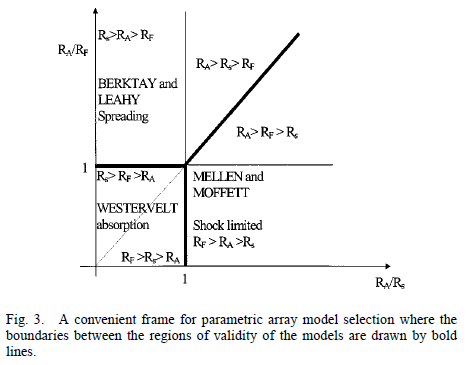

## Reference

- Kopp, L., et al. (2000). "Potential performance of parametric communications." IEEE Journal of Oceanic Engineering 25(3): 282-295.

###     Absorption limited model

- Westervelt, P. J. (1963). "Parametric Acoustic Array." The Journal of the Acoustical Society of America 35(4): 535-537.

###     Spreading limited Model

- Berktay, H. O. and D. J. Leahy (1974). "Farfield performance of parametric transmitters." The Journal of the Acoustical Society of America 55(3): 539-546.

###     Shock-wave limtied model

- Moffett, M. B. and R. H. Mellen (1977). "Model for parametric acoustic sources." The Journal of the Acoustical Society of America 61(2): 325-337.

## 3 basic distances which control the behavior of the parametric array

- Absorption length:                 $R_{A}=L_{a}=\frac{1}{\alpha_{p}\left(f_{p}\right)}$

- Rayleigh distnace:                 $R_{F}=z_{0}
=\frac{1}{2}ka^{2}
=\frac{\pi a^{2}}{\lambda_{p}}
=\frac{\pi a^{2}f_p}{c_{0}}$

- Shock formation distance:    $R_{S}=\bar{x}
=\frac{1}{\beta \varepsilon k_{p}}
=\frac{c_0}{2\pi \beta \varepsilon f_p}
=\frac{c_0^{2}}{2\pi \beta u_p f_p}$

## 3 basic modeling options

- Absorption limited

- Westervelt's initial model

- Design parameter:    $f_{p}$

- Spreading limited

- Berktay and Leahy

- Design parameter:    $f_{p}$, $a$

- Shock-wave limtied

- Mellen and Moffett

- Design parameter:    $f_{p}$, $a$, $u_{p}$

## Gol'dberg representation

- Gol'dberg number:                                                    $X=\Gamma=\frac{R_A}{R_S}=\frac{\beta \varepsilon k_{p}}{\alpha_p}
=\frac{2\pi \beta u_p f_p}{c_0^{2} \alpha \left(f_p \right)}$

- A properly normalized inverse Rayleigh distance:    $Y=\frac{R_A}{R_F}=\frac{\lambda_p}{\alpha_p \pi a^2}

=\frac{c_{0}}{\pi a^{2}f_p \alpha \left( f_p \right)}$

## KZK equation


$$\frac{\partial^2p}{\partial z \partial \tau}
- \frac{c_0}{2} \nabla_\perp^2 p
- \frac{\delta}{2 c_0^3} \frac{\partial^3 p}{\partial \tau^3}
=
\frac{\beta}{2 \rho_0c_0^3} \frac{\partial^2 p^2}{\partial \tau^2}$$


###     Assumption regarding the source

- The source is defined in the plane, $z=0$.

- The source has a characteristic radius, $a$.

- The source radiates at frequencies that satisfy the relation, $ka \gg 1$.

The last assumption ensures that the beam is reaonably directional.

Because of the assumed directionality of the beam, the sound is localized in the vincinty of the $z$ axis, and the wavefronts are quasi-planar.

###     High frequency limit on the parabolic approxiamation

It is necessary to consider the $\mathcal{O} \left( \varepsilon^2 \right)$ in $\nabla^2$.